**Image Rectification Practicum**

In this practicum we will rectify a single image (I) by solving the camera equation (eq. 1) using the specified real world coordinates (a pred-determined x, y, z grid), the camera geometry or extrinsics (beta), and the camera instrinsics (lcp). This practicum is designed to follow the geomDemo, and the test image can be found in that folder.

Needed Variables:

**I** = image to be rectified (test image in geomDemo folder)

**xy** = vector of xy information [xmin dx xmax ymin dy ymax]

**z** = single elevation or grid of z elevations

**beta** = geometry (extrinsics) from specified frame [camera X, camera Y, camera Z, azimuth, tilt, roll] NOTE:all angles are in radians in your local coordinate system. If running findGeomDemo first, beta will be populated. 

**lcp** = intrinsic values. If running findGeomDemo first, lcp will be populated in your workspace. 

First let's define our image coordinates from the size of our Image, **I**:

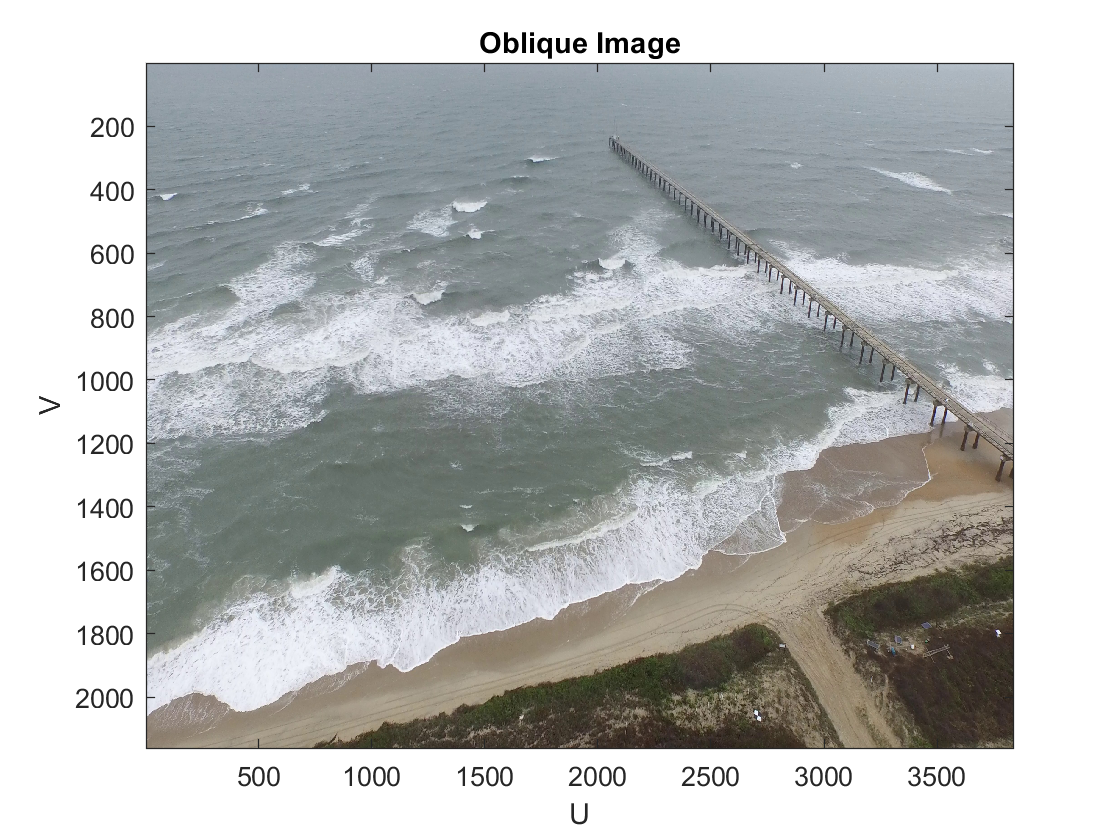

figure;
imagesc(I)
title('Oblique Image')
xlabel('U');ylabel('V')


[NV,NU,NC] = size(I)

NV =         2160


NU =         3840


NC =      3


UI = 1:NU;
VI = [1:NV]';

Now we need to pre-define a grid where our image will be projected:

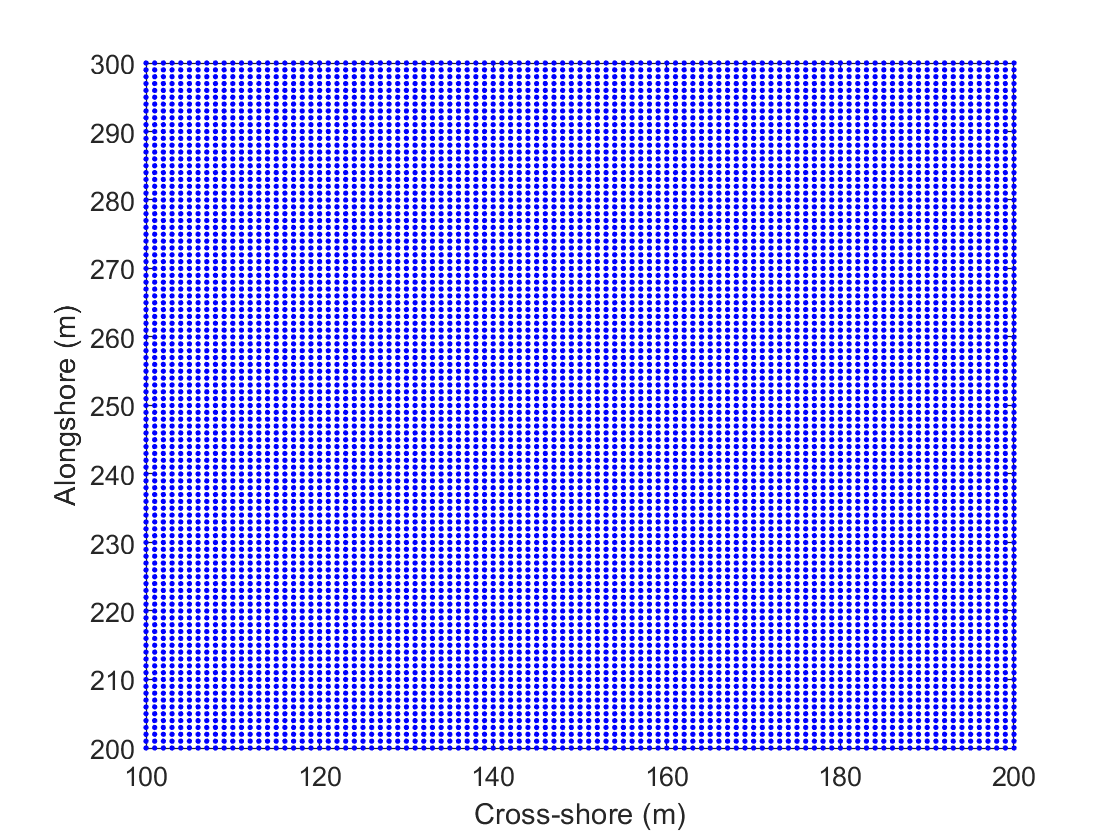

%define a vector of x,y information
xy=[0 1 600 200 1 1000];

%need to assign z coordinates, for now let z = constant 0 (could also be a
%grid of z values equal to the grid defined by xy.
z=0;

%generate our grids:
x = xy(1):xy(2):xy(3); 
y = xy(4):xy(5):xy(6);
[X,Y] = meshgrid(x,y);

if length(z)==1
    xyz = [X(:) Y(:) repmat(z, size(X(:)))];
else
    xyz = [X(:) Y(:) z(:)];
end

%Let's plot it to make sure its what we expected:
figure;
plot(X(:),Y(:),'b.');
axis([100 200 200 300])%zoom in so can see grid cells
xlabel('Cross-shore (m)');
ylabel('Alongshore (m)');

Now, recalling, the Camera Equation: $\left\lbrack \begin{array}{c}
U\\
V\\
1
\end{array}\right\rbrack =\mathrm{KR}\left\lbrack \begin{array}{c}
I|-C
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
Y\\
Z\\
1
\end{array}\right\rbrack$ eq. 1, Let's calculate the Projection Matrix, **P**, where $P=\mathrm{KR}\left\lbrack I|-C\right\rbrack$:

%Calculate P matrix
format longG

%first define K matrix (intrinsics)
lcp=meta.globals.lcp;
K = [lcp.fx 0 lcp.c0U;  
     0 -lcp.fy lcp.c0V;
     0  0 1];

%now define rotation matrix, R (extrinsics)
R = angles2R(beta(4), beta(5), beta(6));

%create identity matrix & camera center coordinates
IC = [eye(3) -beta(1:3)'];

%calculate P
P = K*R*IC;

%make P homogenous
P = P/P(3,4)   

P =            8.9241307853959         -17.9428366381175         -6.22952594884266          12266.4898911449
        -0.658172075310355        0.0972588267307828         -17.7431616169308          1341.15900857441
       0.00606669439493206      -0.00114407633124004      -0.00319490492183763                         1


Now we convert our X,Y,Z world coordinates into UV coordinates:

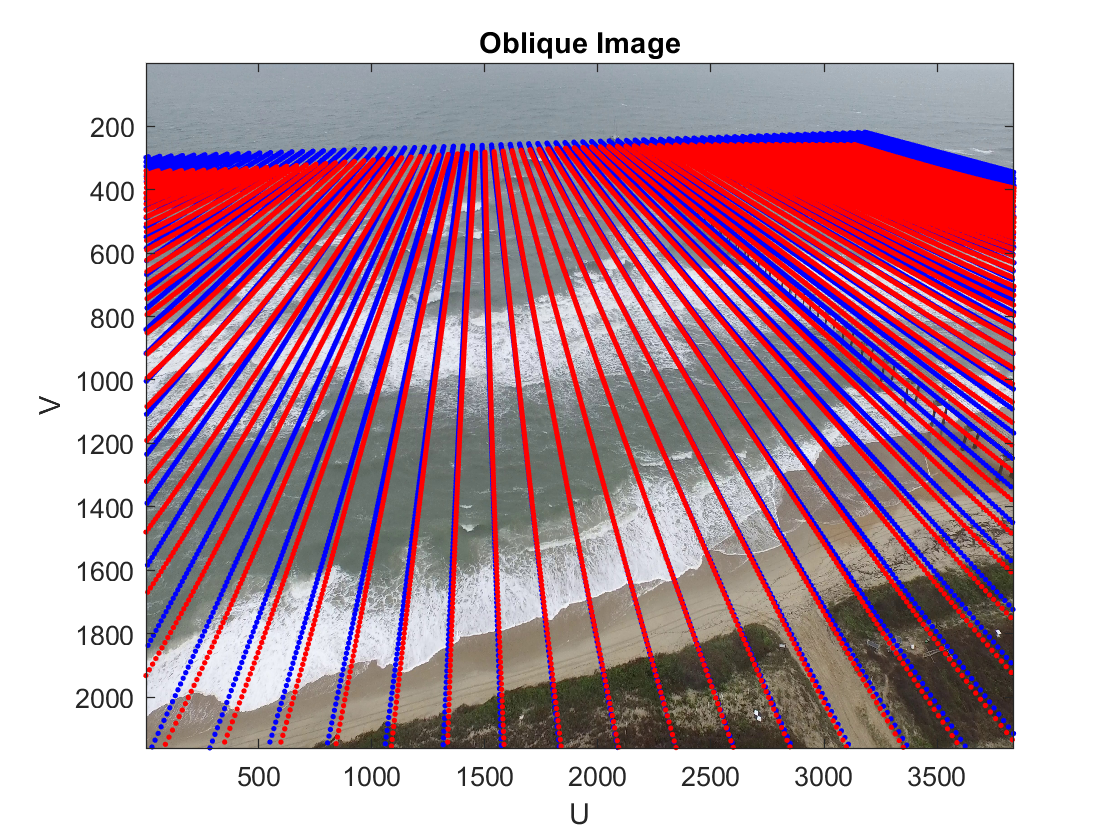

%convert xyz locations to uv coordinates
UV = P*[xyz'; ones(1,size(xyz,1))];

%homogenize UV coordinates (divide by 3 entry)
UV = UV./repmat(UV(3,:),3,1);

%convert undistorted uv coordinates to distorted coordinates
[Ud,Vd] = distort(UV(1,:),UV(2,:),lcp); 
UdVd = round([Ud; Vd]);%round to the nearest pixel locations
UdVd = reshape(UdVd,[],2); %reshape the data into something useable

%find the good pixel coordinates that are actually in the image (your grid
%might extend outside your image)
good = find(onScreen(UdVd(:,1),UdVd(:,2),NU,NV));

%for fun, let's plot the grid on our image
%first reshape into matrix form so easier to plot
Umat=reshape(UV(1,:),length(y),length(x));
Vmat=reshape(UV(2,:),length(y),length(x));
Udmat=reshape(Ud,length(y),length(x));
Vdmat=reshape(Vd,length(y),length(x));
%plot every 10th alongshore transect in grid
figure;
imagesc(I);hold on
plot(Umat(1:10:end,:),Vmat(1:10:end,:),'b.')%undistorted coordinates
plot(Udmat(1:10:end,:),Vdmat(1:10:end,:),'r.')%distorted coordinates
title('Oblique Image')
xlabel('U');ylabel('V')


clear Umat Vmat Udmat Vdmat

Finally, we can interpolate our RGB colors onto our XYZ grid:

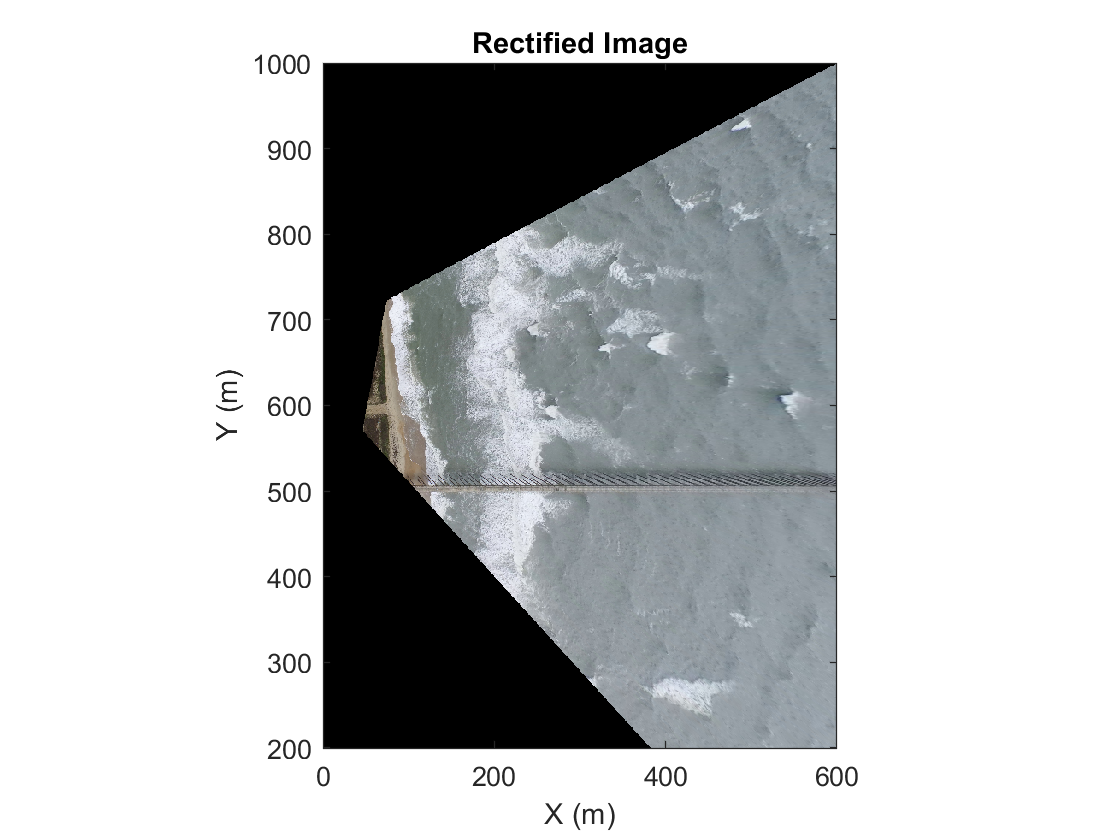

%preallocate final orthophoto
Irect = zeros(length(y),length(x),3);

% cycle through R,G,B intensities
for i = 1:NC    
    singleBandImage = I(:,:,i); %extract the frame
    rgbIntensities = interp2(UI, VI, double(singleBandImage),Ud,Vd); %extract the data at the pixel locations you need
    tempImage = Irect(:,:,i); %preallocate the orthophoto size based on your x,y 
    tempImage(good) = rgbIntensities(good); %fill your extracted pixels into the frame
    Irect(:,:,i) = tempImage; %put the frame into the orthophoto
end

frameRect.x=x;
frameRect.y=y;
frameRect.I=Irect;

%% Plot
figure;
imagesc(frameRect.x,frameRect.y,uint8(frameRect.I));
title('Rectified Image')
xlabel('X (m)');ylabel('Y (m)')
axis xy;axis image